# Worksheet 1: Image Processing - Count and Classify Coins

## Load and Preprocess Images

Read in the image 'coins.png' with the function imread. Use imshow to view the image.

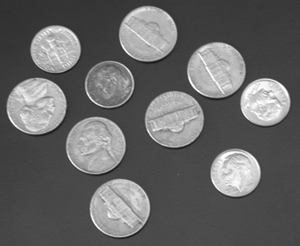

imgOriginal = imread('coins.png');

figure
imshow(imgOriginal)

title("What is the value of the nickels and dimes?")

What size is the image?

sz = size(imgOriginal);

### Measurements in Pixels

A measuring tool, imdistline, lets you measure pixels in an image. Using imdistline, measure the horizontal and vertical dimensions of the coins in the image. How distorted is the image?

Horizontal:

h1 = imdistline(imgca, [66.5, 126.5], [148 148]);

Vertical:

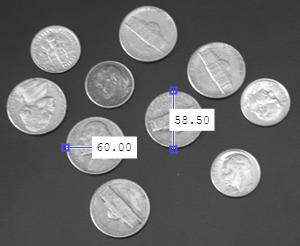

h2 = imdistline(imgca, [174 174], [91 149.5]);

yMult = h1.getDistance/h2.getDistance;

### Resizing

Using imresize, change the dimensions of the image so that the coins are once again circular. Measure once more with imdistline to prove that the horizontal and vertical diameters are now equal.

imgResized = imresize(imgOriginal, ...
    [round(sz(1)*yMult) sz(2)]);
imshow(imgResized)

% Horizontal:
h1 = imdistline(imgca, [66.5 126.5], [150.5 150.5]);
% Vertical:
h2 = imdistline(imgca, [174.5 174.5], [93 153]);

## Segmentation

What is image segmentation? What are different methods you can use to mask or segment part of an image?

img = imgResized;
bw = imbinarize(img);
imshow(bw)

## Not so good...needs some post-processing!

### Imfill

docsearch("fill holes in binary image")

bw = imfill(bw, "holes");
imshow(bw)

### Regionprops

doc regionprops
rng(1)
stats = regionprops("table", bw, "EquivDiameter")

stats = 10×1 table
    EquivDiameter
    _____________

       58.708    
       49.107    
       59.076    
       48.455    
       60.017    
       57.303    
       58.251    
       57.625    
       49.559    
       49.327    


### Find Edges

bwEdge = edge(bw);

imshow(imoverlay(img, bwEdge, "r"))
title("What is the value of the nickels and dimes?")

## KMEANS clustering

So, given the data you have from your figure, what is one way you can distinguish dimes from nickels? Size! Use kmeans clustering to group the coins into two categories.

counts = kmeans(stats.EquivDiameter, 2)

counts =      1
     2
     1
     2
     1
     1
     1
     1
     2
     2



imshow(imgResized)

Count the number of coins in each category.

nNickels = nnz(counts == 1);
nDimes = nnz(counts == 2);
titleString = sprintf("%i Dimes; %i Nickels: Total Value: $%0.2f", ...
    nDimes, nNickels, (nDimes * 0.10 + nNickels * 0.05));
title(titleString)

## CIRCLE DETECTION, directly on grayscale image!

nickelDiam = max(mean(stats.EquivDiameter(counts == 1)), ...
    mean(stats.EquivDiameter(counts == 2)))

nickelDiam = NaN

dimeDiam = min(mean(stats.EquivDiameter(counts == 1)), ...
    mean(stats.EquivDiameter(counts == 2)))

dimeDiam = NaN

%
imageSegmenter(img)
% imageSegmenter used Diameters...
%   round([nickelDiam-3 nickelDiam+3]) % = [55 61]
%   round([dimeDiam-3 dimeDiam+3])     % = [46 52]

## COUNT:

bwNickels = segmentNickels(img);
bwDimes = segmentDimes(img);
nickelStats = bwconncomp(bwNickels)

nickelStats = struct with fields:
    Connectivity: 8
       ImageSize: [252 300]
      NumObjects: 6
    PixelIdxList: {[2767×1 double]  [2766×1 double]  [2779×1 double]  [2612×1 double]  [2707×1 double]  [2693×1 double]}


dimeStats = bwconncomp(bwDimes)

dimeStats = struct with fields:
    Connectivity: 8
       ImageSize: [252 300]
      NumObjects: 4
    PixelIdxList: {[1877×1 double]  [1888×1 double]  [1875×1 double]  [1872×1 double]}


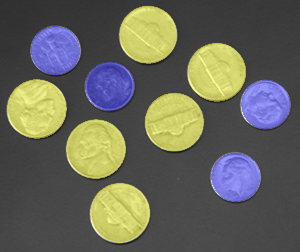



labelMat = zeros(size(img));
labelMat(bwNickels) = 1;
labelMat(bwDimes) = 2;

imshow(labeloverlay(img, labelMat, Transparency = 0.6))
title(sprintf("Total Value: $%0.2f", ...
    0.05 * nickelStats.NumObjects + 0.1 * dimeStats.NumObjects))

## OR, TRY THE CIRCLEFINDER APP:

%CircleFinder(img)
% FILE EXCHANGE:
%
% https://www.mathworks.com/matlabcentral/fileexchange/34365-circle-finder?s_tid=srchtitle

## ALL COINS:

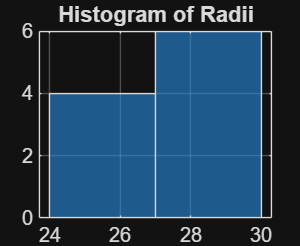

[centers, radii, metric] = imfindcircles(img, [20 30], ...
   'Sensitivity', 0.9100, ...
   'EdgeThreshold', 0.30, ...
   'Method', 'PhaseCode', ...
   'ObjectPolarity', 'Bright');
%

counts = histogram(radii);
title('Histogram of Radii')

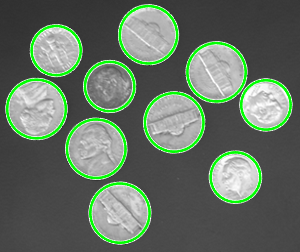

imshow(img)
viscircles(centers, radii, Color = 'g');

%titleString = sprintf("Total Value: $%0.2f", (counts.Values(1) * 0.10 + counts.Values(2) * 0.05));
%title(titleString)

## ALTERNATIVELY, we could select the coins by their radii:

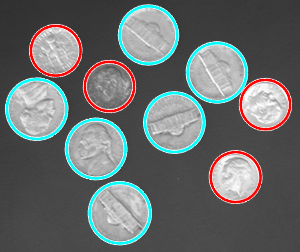

figure
imshow(img)
[dimeCenters, dimeRadii, dimeMetric] = imfindcircles(img, [22 27], ...
   'Sensitivity', 0.895, ...
   'EdgeThreshold', 0.30, ...
   'Method', 'PhaseCode', ...
   'ObjectPolarity', 'Bright');
viscircles(dimeCenters, dimeRadii, Color = 'r');
%  
[nickelCenters, nickelRadii, nickelMetric] = imfindcircles(img, [27 32], ...
   'Sensitivity', 0.92, ...
   'EdgeThreshold', 0.30, ...
   'Method', 'PhaseCode', ...
   'ObjectPolarity', 'Bright');
viscircles(nickelCenters, nickelRadii, Color = 'c');
titleString = sprintf("Total Value: $%0.2f", (numel(dimeRadii) * 0.10 + numel(nickelRadii) * 0.05));
title(titleString)